We want to see how well we can reorder the outcome of an apporximate search based on low-dimensional embeddings. We'll start off by using the high-dim laion data set, and the 32-dim ground truth.


clear variables;
[data32,queries32] = get_data_and_queries_32dim();


[gt_nns,gt_dists] = get_ground_truth_100_32();


data768 = h5read("/Volumes/Data/laion/laion2B-en-clip768v2-n=300K.h5","/emb");
data768 = data768';
pivots768 = data768(20000:21000,:);
data768 = data768(1:100*1000,:);

queries768 = h5read("/Volumes/Data/laion/public-queries-10k-clip768v2.h5","/emb");
queries768 = queries768';

gold_s_dists = h5read("/Volumes/Data/laion/laion2B-en-public-gold-standard-v2-100K.h5","/dists");
gold_s_nns = h5read("/Volumes/Data/laion/laion2B-en-public-gold-standard-v2-100K.h5","/knns");
gold_s_dists = gold_s_dists';
gold_s_nns = gold_s_nns';



let's just check we have a compatible ground truth...

% query1 = queries768(1,:);
% q1dists = euc(query1,data768);
% 
% [ds,nns] = sort(q1dists);
% nns(1:5)
% q1gt = gold_s_nns(1,1:5);
% q1gt'



Now let's see how good using 32 dim PCA is

query_no = 2;

query_32 = queries32(query_no,:);
q1_32_dists = euc(query_32,data32);
[~,nns_32] = sort(q1_32_dists);
size(intersect(nns_32(1:100),gold_s_nns(query_no,:)),1)

ans = 62

overlap_1k = size(intersect(nns_32(1:1000),gold_s_nns(query_no,:)),1)

overlap_1k = 97

overlap_10k = size(intersect(nns_32(1:10000),gold_s_nns(query_no,:)),1)

overlap_10k = 100

OK all looks fine. almost all results in top 10k, three-quarters in top 1k, a bit less than half in top 100.

So now let's check the nns returned by the 32 dim search using a low-dim embedding based on the 768 dim data


low_dims = 100;
simp1 = NsimpProjection(pivots768(1:low_dims,:),low_dims,@euc);
simp2 = NsimpProjection(pivots768(100:99+low_dims,:),low_dims,@euc);


nns = nns_32(query_no,:);
% get the full dim data corresponding to the 32dim 1000 nns
approx_data = data768(nns_32(1:1000),:);
query = queries768(query_no,:);

qproj = simp1.project(query);
projs = zeros(1000,low_dims);
for i = 1 : 1000
    pr = simp1.project(approx_data(i,:));
    projs(i,:) = pr;
    projs(i,:) = simp2.project(approx_data(i,:));simp1.project(approx_data(i,:));
end




gt_dists = euc(query,approx_data);
proj_dists = euc(qproj,projs);
proj_dists_z = zen(qproj,projs);

% 
% proj_dists = max(proj_dists,proj_dists2);
% proj_dists_z = max(proj_dists_z,proj_dists_z2);


[sorted_gt, ord] = sort( gt_dists);
sorted_dists = proj_dists(ord);
sorted_zens = proj_dists_z(ord);

scatter(gt_dists,proj_dists);

scatter(gt_dists,proj_dists_z);

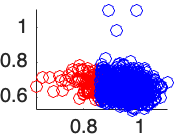


figure;
hold on;
scatter(sorted_gt(1:overlap_1k),sorted_dists(1:overlap_1k),"red");
scatter(sorted_gt(overlap_1k+1:end),sorted_dists(overlap_1k+1:end),"blue");
hold off;

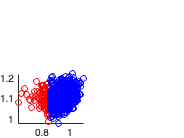


figure;
hold on;
scatter(sorted_gt(1:overlap_1k),sorted_zens(1:overlap_1k),"red");
scatter(sorted_gt(overlap_1k+1:end),sorted_zens(overlap_1k+1:end),"blue");
hold off;